# Live streaming Speech Recognition with Audio File in MATLAB with co-Execution in Python

## Python Environment Setup

Refer to the steps outlined in [README.md](matlab:open('./README.md')) to ensure your Python environment is correctly set up.

Ensure the folder containing all helper code files is on your MATLAB path.

addpath("HelperFiles");

## Audio File Setup

Setup the audio file for input. The inference method in Python requires an audio input of 2560 samples per frame with a sampling frequency of 16 kHz and then write it into a `dsp.AsyncBuffer` object and intialize it with a vector of zeros.

segmentLength = 2560;
contextLength = 640;
context = zeros(contextLength,1);
Fs = 16000;
asyncBuffStreaming = dsp.AsyncBuffer(1e6);
write(asyncBuffStreaming, context);
audioFileName = 'ttls.wav';
afr = dsp.AudioFileReader(audioFileName, 'SamplesPerFrame', segmentLength+contextLength);
adw = audioDeviceWriter('SampleRate', afr.SampleRate);

## Streaming Speech-To-Text

Instantiate the deep learning model. This is a class defined in Python. You will call methods on this object during audio inference.

recognizer = py.Live_Stream_Speech_Recognition.SpeechRecognizer();

In a loop, read the audio from the file, write it onto the async buffer, read samplesPerFrame samples from the async buffer and perform speech-to-text.

transcriptionStack = struct;
i = 1;
txt = "";
tic
while any(peek(asyncBuffStreaming)) || ~isDone(afr)
    audio = afr(); 
    finalAudio = read(asyncBuffStreaming, segmentLength+contextLength, contextLength);
    adw(audio);
    newtxt = string(recognizer.streamingInfer(finalAudio));
    transcriptionStack(i).time = toc;
    transcriptionStack(i).text = newtxt;
    transcriptionStack(i).audio = audio;
    i = i+1;
    write(asyncBuffStreaming, audio);
    if ~isequal(newtxt, "")
        txt = txt + newtxt
    end 
end

txt = " twink"

txt = " twinkle"

txt = " twinkle tw"

txt = " twinkle twink"

txt = " twinkle twinkle"

txt = " twinkle twinkle little"

txt = " twinkle twinkle little star"

txt = " twinkle twinkle little star oh"

txt = " twinkle twinkle little star oh i"

txt = " twinkle twinkle little star oh i wonder"

txt = " twinkle twinkle little star oh i wonder what"

txt = " twinkle twinkle little star oh i wonder what you"

txt = " twinkle twinkle little star oh i wonder what you are"

txt = " twinkle twinkle little star oh i wonder what you are up"

txt = " twinkle twinkle little star oh i wonder what you are up above"

txt = " twinkle twinkle little star oh i wonder what you are up above the"

txt = " twinkle twinkle little star oh i wonder what you are up above the world"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so high"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so high like"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so high like a"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so high like a diamond"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so high like a diamond in"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so high like a diamond in the"

txt = " twinkle twinkle little star oh i wonder what you are up above the world so high like a diamond in the sky"

## Plot Audio Waveforms and the corresponding transcription in time.

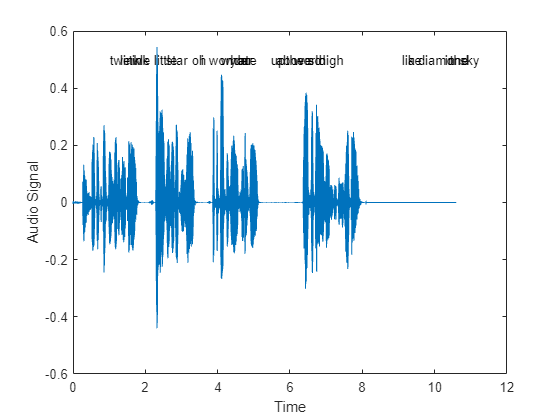

plotAudioWaveFormWithTranscription(transcriptionStack);

## Non Streaming Speech-To-Text

You can also pass the entire audio file data into the nonStreamingInfer method of the recognizer object. However, as expected the result comes out with a bit of a delay

txt = string(recognizer.nonStreamingInfer(audioread(audioFileName)))
release(afr); 
release(adw);
cd(currDir);

*Copyright 2023 The MathWorks, Inc.*